# **Figure 10**

This m-file is written according  to  the paper entitled :

 "**An Efficient Low-Complexity Method to Calculate Hybrid Beamforming Matrices for mmWave Massive MIMO Systems**" 

you can see the paper on this link:  [https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=9442813)

## **Authors: **

**1- Jamal Beiranvand** 

    Website: 

    e-mail: Jamalbeiranvand@gmail.com

    google scholar:  [https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en](https://scholar.google.com/citations?user=S6LywwsAAAAJ&hl=en)

2- **Vahid Meghdadi**

    website: [https://www.unilim.fr/pages_perso/vahid/](https://www.unilim.fr/pages_perso/vahid/) 

    e-mail: meghdadi@ensil.unilim.fr

    google scholar:  [https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en](https://scholar.google.com/citations?user=_HYFga8AAAAJ&hl=en)

## Required Functions to run

All functions used in this code are in the** "Functions" **folder, described in the **"MATLAB Functions" **document.

**Note: **change  the path of **Functions** folder according its path in your PC.

Date : 02/07/2021

By Jamal Beiranvand

clear;
clc
warning off
%% User pannel Parameters (you may have to change some values in the "Plot" section)
addpath(genpath('C:\Users\Jamal\OneDrive\Jamal\MATLAB Code\Functions'))% Add path of the "Functions" folder.
K=20;                           % number of users
% Bits = 3;                    % Values of Bits, it can be a vector, you can use 'inf' for infinity resolution
Txz = 12;                       % Number of the transmitter antennas on z axis
Txy =12;                      % Number of the transmitter antennas on y axis
Rxz = 1;                       % Number of the receiver antennas on z axis
Rxy = 1;                       % Number of the receiver antennas on y axis
% Ns  = 1;                       % Number of data streams
% NrfTx = 9;                     % Number of RF chains at BS
Ncl =5;                       % Number of Channel clusters(Scatters)
Nray= 10;                       % Number of rays in each cluster
AngSpread = 10;       % Angle spread, standard deviation of the angles in azimuth and elevation both of Rx and Tx
TxSector=[60 360];
RxSector=[20 360];
SNR_dB = -20:2:10;             % Signal to noise ratio in dB
realization = 200;              % Iteration of simulation
%% Initialize Parameters
Tx  = [Txz,Txy];               % Srtucture of the transmit antanna array
Rx  = [Rxz,Rxy];               % Srtucture of the receiver antanna array 
Nt  = Txz*Txy;                 % Number of the transmit antennas
Nr  = Rxz*Rxy;                 % Number of the receive antennas
SNR = 10.^(SNR_dB./10);        
%% Allocate memory space for matrices
R_MMSE=zeros(length(SNR_dB),realization);
R_ZF=zeros(length(SNR_dB),realization);
R_MRC=zeros(length(SNR_dB),realization);
Novelmmse=zeros(length(SNR_dB),realization);
Novelzf=zeros(length(SNR_dB),realization);
Novelmrc=zeros(length(SNR_dB),realization);

R_Shr=zeros(length(SNR_dB),realization);
R=zeros(K,1);
%%
[Setb,Sb]=GenUniqueSet(16);
for r=1:length(SNR_dB)
     formatSpec = 'Step %i of %i \n';
    fprintf(formatSpec,r,length(SNR_dB))
    Snr=SNR(r);
    for reali=1:realization
        % generate channel
        [H,At,Ar,~]=MU_Channel(Tx,K,Ncl,'Nray',Nray,'AngSpread',AngSpread);
        
        % Full Digital MMSE beamforming
        Fmmse=MMSE_Down(H,Snr);
        Gmmse= diag(ones(K,1))*sqrt(Snr);
        R_MMSE(r,reali)=SumRate(H,Fmmse,Gmmse);
         % Novel with MMSE precoder
        [FRF_Nov,FBB_Nov] = MUMISO_Down(Fmmse,Setb,Sb);
        G= diag(ones(K,1))*sqrt(Snr/K);
        Novelmmse(r,reali)=SumRate(H,FRF_Nov*FBB_Nov,G);
           
        % Full Digital ZF beamforming
        Fzf=ZF_Down(H);
        Gzf= diag(ones(K,1))*sqrt(Snr);
        R_ZF(r,reali)=SumRate(H,Fzf,Gzf);
        % Novel with ZF precoder
        [FRF_zf,FBB_zf] = MUMISO_Down(Fzf,Setb,Sb);
        G= diag(ones(K,1))*sqrt(Snr/K);
        Novelzf(r,reali)=SumRate(H,FRF_zf*FBB_zf,G);

        
        % Full Digital MRC beamforming
        Fmrc=MRC_Down(H);
        Gmrc= diag(ones(K,1))*sqrt(Snr);
        R_MRC(r,reali)=SumRate(H,Fmrc,Gmrc);
        % Novel with MRC precoder
        [FRF_Nov,FBB_Nov] = MUMISO_Down(Fmrc,Setb,Sb);
        G= diag(ones(K,1))*sqrt(Snr/K);
        Novelmrc(r,reali)=SumRate(H,FRF_Nov*FBB_Nov,G);
        
    end
end

Step 1 of 16 
Step 2 of 16 
Step 3 of 16 
Step 4 of 16 
Step 5 of 16 
Step 6 of 16 
Step 7 of 16 
Step 8 of 16 
Step 9 of 16 
Step 10 of 16 
Step 11 of 16 
Step 12 of 16 
Step 13 of 16 
Step 14 of 16 
Step 15 of 16 
Step 16 of 16 


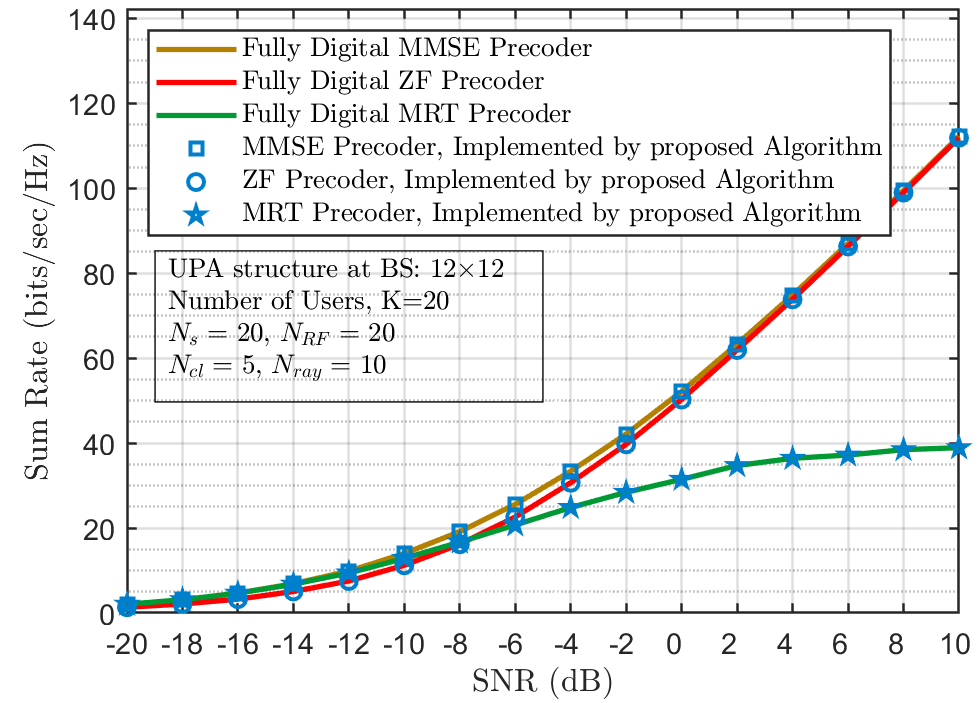

Data1= sum((R_MMSE),2)/realization;
Data2= sum(R_ZF,2)/realization;
Data3= sum(R_MRC,2)/realization;
Data4= sum(Novelmmse,2)/realization;
Data5= sum(Novelzf,2)/realization;
Data6= sum(Novelmrc,2)/realization;
%% plot 

Xaxis= SNR_dB;
Fig=figure;
hold on
P1=plot(Xaxis,Data1);
P2=plot(Xaxis,Data2);
P3=plot(Xaxis,Data3);
P4=plot(Xaxis,Data4);
P5=plot(Xaxis,Data5);
P6=plot(Xaxis,Data6);

Legend1='Fully Digital MMSE Precoder';
Legend2='Fully Digital ZF Precoder';
Legend3='Fully Digital MRT Precoder';
Legend4='MMSE Precoder, Implemented by proposed Algorithm';
Legend5='ZF Precoder, Implemented by proposed Algorithm';
Legend6='MRT Precoder, Implemented by proposed Algorithm';

% Legend4='Proposed Hybrid BF Alg for $b=1$, $N_{RF}=N_s+3 $';
% Legend5=' Quantized-Hybrid BF in [31] (OMP)';

% P1 properties
set(P1,'LineStyle','-');           % '-' , '--' , ':' , '-.' , 'none'
set(P1,'Marker','none');       % 'o' , '+'  , '*' , 'x' ,'s' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram', 'none'
set(P1,'LineWidth',2);
set(P1,'Color',[.7 .5 0]);
set(P1,'MarkerSize',7);
P1_group= hggroup;set(P1,'Parent',P1_group);
set(get(get(P1_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on'); 
% P1.MarkerIndices =[ 1 6];

% P2 properties
set(P2,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P2,'Marker','none');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P2,'LineWidth',2);
set(P2,'Color','r');
set(P2,'MarkerSize',7);
P2_group= hggroup;set(P2,'Parent',P2_group);
set(get(get(P2_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% P2 properties
set(P3,'LineStyle','-');           % '-' , '--' , ':' , '-.'
set(P3,'Marker','none');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P3,'LineWidth',2);
set(P3,'Color',[0 .6 .2]);
set(P3,'MarkerSize',7);
P3_group= hggroup;set(P3,'Parent',P3_group);
set(get(get(P3_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');
% 
% P2 properties
set(P4,'LineStyle','none');           % '-' , '--' , ':' , '-.'
set(P4,'Marker','s');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P4,'LineWidth',1.5);
set(P4,'Color',[0.0 .5 .8]);
set(P4,'MarkerSize',6);
P4_group= hggroup;set(P4,'Parent',P4_group);
set(get(get(P4_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

% P2 properties
set(P5,'LineStyle','none');           % '-' , '--' , ':' , '-.'
set(P5,'Marker','o');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P5,'LineWidth',1.5);
set(P5,'Color',[0.0 .5 .8]);
set(P5,'MarkerSize',6);
P5_group= hggroup;set(P5,'Parent',P5_group);
set(get(get(P5_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');

set(P6,'LineStyle','none');           % '-' , '--' , ':' , '-.'
set(P6,'Marker','pentagram');       % 'o' , '+'  , '*' , 'x' , 's' , '^' , 'v' , '>' , '<' , 'pentagram', 'hexagram'
set(P6,'LineWidth',1.5);
set(P6,'Color',[0.0 .5 .8]);
set(P6,'MarkerSize',6);
P6_group= hggroup;
set(P6,'Parent',P6_group);
set(get(get(P6_group,'Annotation'),'LegendInformation'),'IconDisplayStyle','on');


lgd=legend(Legend1,Legend2,Legend3,Legend4,Legend5,Legend6);
% Axes Properties 
ax=gca;
ax.XLim = [min(Xaxis) max(Xaxis)];
 ax.YLim = [0 max(Data1)+30];
ax.XTick = Xaxis;
% ax.YTick = 0:5:50;
ax.XTickLabel=Xaxis;
ax.XLabel.String='SNR (dB)';
ax.YLabel.String='Sum Rate (bits/sec/Hz)';
ax.XGrid='on';
ax.YGrid='on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.YLabel.Interpreter='latex';
ax.XLabel.Interpreter='latex';
ax.FontSize = 11;
ax.LineWidth = .9;
ax.Box='on';

% Legend Properties %
lgd.Location= 'northwest'; %%
lgd.Box='on';
lgd.LineWidth=.9;
lgd.Interpreter='latex';
lgd.FontSize = 10;
% 
% Figure Properties
ax.Units='centimeters';
ax.Position = [ax.TightInset(1)+ax.TightInset(3) ax.TightInset(2) 11 8];
Fig.Units='centimeters';
Fig.Position = [10 5 (ax.TightInset(1)+ 2*ax.TightInset(3)+ ax.Position(3) ) (ax.TightInset(2)+ ax.TightInset(4)+ ax.Position(4))];

%%  Creat notation 
Not1=annotation('textbox');
X_points=[-19 -5];
Y_points=[ .35*(diff(ax.YLim)) .60*(diff(ax.YLim))];
str1=['UPA structure at BS: ',num2str(Tx(1)),'$\times$',num2str(Tx(2))];
str2=['Number of Users, K=',num2str(K)];
str3=['$N_{s}=$ ',num2str(K),',  $N_{RF}=$ ',num2str(K)];
str4=['$N_{cl}=$ ',num2str(Ncl),',  $N_{ray}=$ ',num2str(Nray)];
Not1.String={str1,str2,str3,str4};
Not1.FontSize = 10;
Not1.Interpreter='latex';
Not1.Units='centimeters';
Dx=ax.Position(3)/(diff(ax.XLim));
Dy=ax.Position(4)/(diff(ax.YLim));
x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
Not1.Position=[x_begin y_begin  x_End y_End];

% % 
% Ell=annotation('ellipse');
% X_points=[19 21];
% Y_points=[25 55];
% Ell.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Ell.Position=[x_begin y_begin  x_End y_End];
% 
% Textarrow1=annotation('textarrow');
% X_points=[8 8];
% Y_points=[30 62];
% str1=['$b_{ps}^{t}=b_{ps}^{r}=\infty$'];
% Textarrow1.String={str1};
% Textarrow1.Interpreter='latex';
% Textarrow1.FontSize = 10;
% Textarrow1.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow1.Position=[x_begin y_begin  x_End y_End];
% %%
% Ell2=annotation('ellipse');
% X_points=[19 21];
% Y_points=[90 125];
% Ell2.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Ell2.Position=[x_begin y_begin  x_End y_End];
% 
% Textarrow2=annotation('textarrow');
% X_points=[16 16];
% Y_points=[30 81];
% str1=['$b_{ps}^{t}=b_{ps}^{r}=$',num2str(B_Vec{2})];
% Textarrow2.String={str1};
% Textarrow2.Interpreter='latex';
% Textarrow2.FontSize = 10;
% Textarrow2.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow2.Position=[x_begin y_begin  x_End y_End];
% %%
% Ell3=annotation('ellipse');
% X_points=[19 21];
% Y_points=[140 185];
% Ell3.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Ell3.Position=[x_begin y_begin  x_End y_End];
% 
% Textarrow3=annotation('textarrow');
% X_points=[24 24];
% Y_points=[30 90];
% str1=['$b_{ps}^{t}=b_{ps}^{r}=$',num2str(B_Vec{3})];
% Textarrow3.String={str1};
% Textarrow3.Interpreter='latex';
% Textarrow3.FontSize = 10;
% Textarrow3.Units='centimeters';
% Dx=ax.Position(3)/(diff(ax.XLim));
% Dy=ax.Position(4)/(diff(ax.YLim));
% x_begin=ax.Position(1)-ax.XLim(1)*Dx+X_points(1)*Dx;
% y_begin=ax.Position(2)-ax.YLim(1)*Dy+Y_points(1)*Dy;
% x_End=(ax.Position(1)-ax.XLim(1)*Dx+X_points(2)*Dx)-x_begin;
% y_End=(ax.Position(2)-ax.YLim(1)*Dy+Y_points(2)*Dy)-y_begin;
% Textarrow3.Position=[x_begin y_begin  x_End y_End];